Code for Assignment_3_Heesoo Kim

syms m zeta k c F0 omega real
assumeAlso(m > 0);
assumeAlso(k > 0);
assumeAlso(c > 0);

syms x(t)
c = zeta*2*sqrt(m*k);
xp = diff(x, t);
xpp = diff(xp, t);
Eq = m*xpp + k*x + c*xp;
solution_forced = dsolve(Eq == F0*sin(omega*t));

vr = symvar(solution_forced)

$$vr = \left(\begin{array}{cccccccc} C_{1} & C_{2} & F_{0} & k & m & \omega & t & \zeta \end{array}\right)$$

solution_forced = subs(solution_forced, [m, k, F0, vr(1), vr(2)], [50e-3, 1000, 1, 0, 0])

$$solution\_forced = \begin{array}{l} \frac{\sqrt{20}\,\sqrt{1000}\,{\mathrm{e}}^{-\sqrt{20}\,t\,\left(\sigma_{1}+\sqrt{1000}\,\zeta \right)}\,{\mathrm{e}}^{\sqrt{20}\,\left(\sqrt{1000}\,t\,\zeta +\sqrt{1000}\,t\,\sigma_{5}\right)}\,\left(\sigma_{2}-\sqrt{20}\,\sin\left(\omega \,t\right)\,\sigma_{4}\right)}{2000\,\sigma_{5}\,\left(20\,{\sigma_{4}}^{2}+\omega^{2}\right)}-\frac{\sqrt{20}\,\sqrt{1000}\,{\mathrm{e}}^{\sqrt{20}\,t\,\left(\sigma_{1}-\sqrt{1000}\,\zeta \right)}\,{\mathrm{e}}^{\sqrt{20}\,\left(\sqrt{1000}\,t\,\zeta -\sqrt{1000}\,t\,\sigma_{5}\right)}\,\left(\sigma_{2}-\sqrt{20}\,\sin\left(\omega \,t\right)\,\sigma_{3}\right)}{2000\,\sigma_{5}\,\left(20\,{\sigma_{3}}^{2}+\omega^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1000}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}\\ \sigma_{2}=\omega \,\cos\left(\omega \,t\right)\\ \sigma_{3}=\sqrt{1000}\,\zeta -\sqrt{1000}\,\sigma_{5}\\ \sigma_{4}=\sqrt{1000}\,\zeta +\sqrt{1000}\,\sigma_{5}\\ \sigma_{5}=\sqrt{\zeta^{2}-1} \end{array}$$

solution_forced = simplify(solution_forced)

$$solution\_forced = -\frac{20\,\omega^{2}\,\sin\left(\omega \,t\right)-400000\,\sin\left(\omega \,t\right)+4000\,\sqrt{2}\,\omega \,\zeta \,\cos\left(\omega \,t\right)}{\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000}$$

solution_forced = simplify(solution_forced)

$$solution\_forced = -\frac{20\,\omega^{2}\,\sin\left(\omega \,t\right)-400000\,\sin\left(\omega \,t\right)+4000\,\sqrt{2}\,\omega \,\zeta \,\cos\left(\omega \,t\right)}{\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000}$$


As = subs(solution_forced, t, 0)

$$As = -\frac{4000\,\sqrt{2}\,\omega \,\zeta }{\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000}$$

Bs = subs(solution_forced, t, pi()/2/omega)

$$Bs = -\frac{20\,\omega^{2}-400000}{\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000}$$

amplitude = sqrt(As^2+Bs^2)

$$amplitude = \sqrt{\frac{{\left(20\,\omega^{2}-400000\right)}^{2}}{{\left(\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000\right)}^{2}}+\frac{32000000\,\omega^{2}\,\zeta^{2}}{{\left(\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000\right)}^{2}}}$$


syms r real % r is ratio 
Y = amplitude*k/F0

$$Y = \frac{k\,\sqrt{\frac{{\left(20\,\omega^{2}-400000\right)}^{2}}{{\left(\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000\right)}^{2}}+\frac{32000000\,\omega^{2}\,\zeta^{2}}{{\left(\omega^{4}+80000\,\omega^{2}\,\zeta^{2}-40000\,\omega^{2}+400000000\right)}^{2}}}}{F_{0}}$$

vr1 = symvar(Y)

$$vr1 = \left(\begin{array}{cccc} F_{0} & k & \omega & \zeta \end{array}\right)$$

Y = subs(Y, [k, F0, omega], [1000, 1, sqrt(1000/50e-3)*r])

$$Y = 1000\,\sqrt{\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}+1600000000\,r^{2}\,\zeta^{2}-800000000\,r^{2}+400000000\right)}^{2}}+\frac{640000000000\,r^{2}\,\zeta^{2}}{{\left(400000000\,r^{4}+1600000000\,r^{2}\,\zeta^{2}-800000000\,r^{2}+400000000\right)}^{2}}}$$

Y1 = subs(Y, zeta, 0.0)

$$Y1 = 1000\,\sqrt{\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}-800000000\,r^{2}+400000000\right)}^{2}}}$$

Y2 = subs(Y, zeta, 0.1)

$$Y2 = 1000\,\sqrt{\frac{6400000000\,r^{2}}{{\left(400000000\,r^{4}-784000000\,r^{2}+400000000\right)}^{2}}+\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}-784000000\,r^{2}+400000000\right)}^{2}}}$$

Y3 = subs(Y, zeta, 0.2)

$$Y3 = 1000\,\sqrt{\frac{25600000000\,r^{2}}{{\left(400000000\,r^{4}-736000000\,r^{2}+400000000\right)}^{2}}+\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}-736000000\,r^{2}+400000000\right)}^{2}}}$$

Y4 = subs(Y, zeta, 0.3)

$$Y4 = 1000\,\sqrt{\frac{57600000000\,r^{2}}{{\left(400000000\,r^{4}-656000000\,r^{2}+400000000\right)}^{2}}+\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}-656000000\,r^{2}+400000000\right)}^{2}}}$$

Y5 = subs(Y, zeta, 0.5)

$$Y5 = 1000\,\sqrt{\frac{160000000000\,r^{2}}{{\left(400000000\,r^{4}-400000000\,r^{2}+400000000\right)}^{2}}+\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}-400000000\,r^{2}+400000000\right)}^{2}}}$$

Y6 = subs(Y, zeta, 1)

$$Y6 = 1000\,\sqrt{\frac{640000000000\,r^{2}}{{\left(400000000\,r^{4}+800000000\,r^{2}+400000000\right)}^{2}}+\frac{{\left(400000\,r^{2}-400000\right)}^{2}}{{\left(400000000\,r^{4}+800000000\,r^{2}+400000000\right)}^{2}}}$$

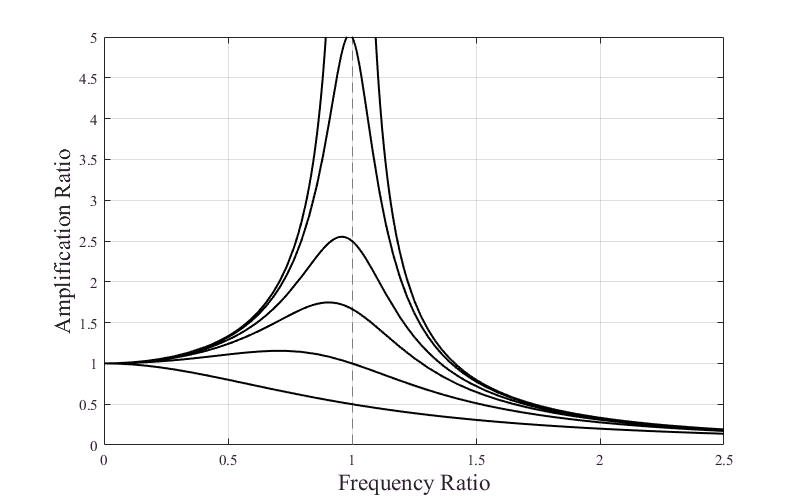


figure
set(gcf,'paperunits','inches')
set(gcf,'position',[5 5 800 500])
fplot(Y1,[0,2.5],'Color','black','LineWidth',1.5)
hold on
fplot(Y2,[0,2.5],'Color','black','LineWidth',1.5)
hold on
fplot(Y3,[0,2.5],'Color','black','LineWidth',1.5)
hold on
fplot(Y4,[0,2.5],'Color','black','LineWidth',1.5)
hold on
fplot(Y5,[0,2.5],'Color','black','LineWidth',1.5)
hold on
fplot(Y6,[0,2.5],'Color','black','LineWidth',1.5)
% title('Amplitude','FontWeight','normal','FontName','Times','Fontsize',16)
set(gca,'XLim',[0 2.5],'Fontsize',11,'FontName','Times')
set(gca,'YLim',[0 5],'Fontsize',11,'FontName','Times')
xlabel('Frequency Ratio','Fontsize',17,'FontName','Times')
ylabel('Amplification Ratio','Fontsize',17,'FontName','Times')

grid on    
% print('forcedResponse','-depsc')
print('forcedResponse','-dmeta')